# VEHICLE SYSTEM DYNAMICS AND CONTROL - HOMEWORK 2

## AYLIN OZTURK 20016928

clear all
clc
close all

## INTRODUCTION INFORMATIONS


%these values are given to us in the homework
x=2+0+0+1+6+9+2+8;
mu = 0.7;
Cf = 145000;   % N/rad
Cr = 185000;   % N/rad
m = 1500+x;      % kg (x = 8)
Iz = 2400+x;     % kg*m^2 (x = 8)
lf = 1.1;      % m
lr = 1.5;      % m
v = 20;        % m/s

% State-space A matrix elements
A11 = (-mu * (Cf + Cr)) / (m * v);
A12 = -1 + (mu * (Cr * lr - Cf * lf)) / (m * v^2);
A21 = (mu * (Cr * lr - Cf * lf)) / Iz;
A22 = (-mu * (Cf * lf^2 + Cr * lr^2)) / (Iz * v);

B11= (mu*Cf)/(m*v);
B12=0;
B21= (mu*Cf*lf)/Iz;
B22= 1/ Iz;

## PART A

% Define A and B matrices
A = [A11, A12; A21, A22];
B=[B11,B12; B21,B22];
disp('A matrix:');

A matrix:


disp(A);

   -7.5589   -0.8649
   34.0198   -8.5294



Cont=[B A*B]; %our controllbility matrix

if rank(Cont) == 2 % checking whether system is controllable or not
    disp("system is  controllable");   
end

system is  controllable


trace_A = A11 + A22;
det_A = A11*A22 - A12*A21;

% Compute eigenvalues 
lambda1 = (trace_A + sqrt(trace_A^2 - 4*det_A)) / 2;
lambda2 = (trace_A - sqrt(trace_A^2 - 4*det_A)) / 2;
disp('eigenvalues of A:')

eigenvalues of A:


disp(lambda1); disp(lambda2);

  -8.0442 + 5.4025i

  -8.0442 - 5.4025i



% Eigenvalues must be on the left half plane to be stable
if real(lambda1) < 0 && real(lambda2) < 0
    disp('The open-loop system is STABLE');
else
    disp('The open-loop system is UNSTABLE');
end

The open-loop system is STABLE


## PART B

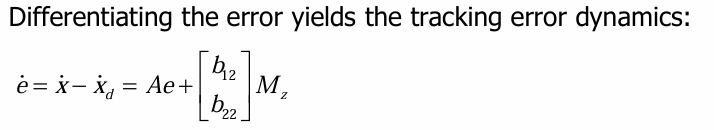

% Error Dynamics are given as e_dot = A * e + B_error * Mz
B_error = B(:,2);  % sadece Mz etkisi
C=eye(2);
D=zeros(2,1);
sys_error = ss(A, B_error,C , D);
disp('Error dynamics state-space model when input is Mz only:');

Error dynamics state-space model when input is Mz only:


sys_error


sys_error =
 
  A = 
            x1       x2
   x1   -7.559  -0.8649
   x2    34.02   -8.529
 
  B = 
              u1
   x1          0
   x2  0.0004119
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


% Compute desired yaw rate r_d
numerator = Cf * Cr * (lf + lr) * v;
denominator = (Cr * Cf * (lf + lr)^2) + (Cr * lr - Cf * lf) * m * v^2;


## PART C

## The simulink model where we model our system and get the results

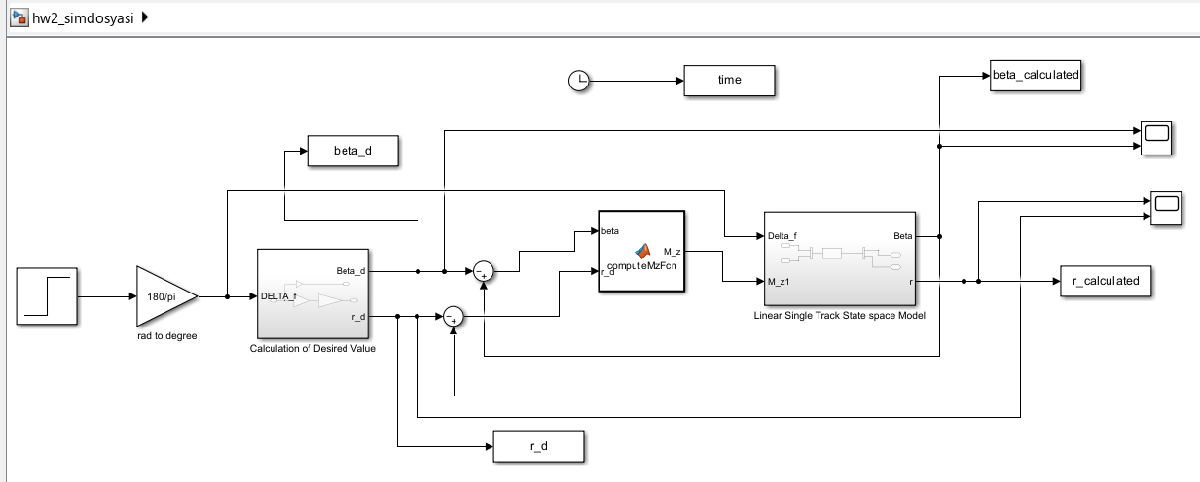

## Inside of the calculation of desired values where we calculated our desired beta and r values

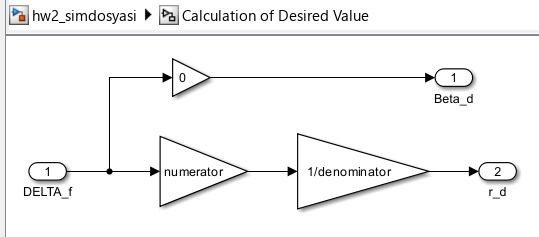

## Inside of the Linear Single Track State Space Model where we model our systems dynamics in to state-space model

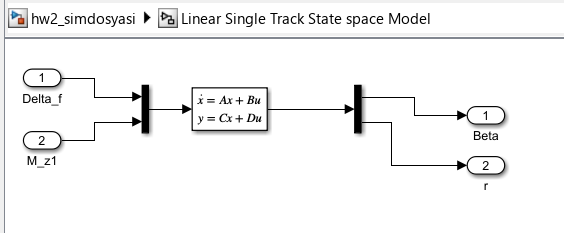

## Inside of the Matlab function where we calculate our M_z with the help of beta , r and K values from the calculation of LQR

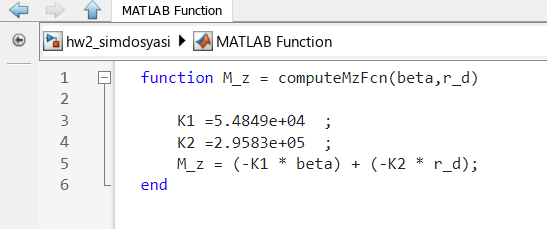

## The gains k1 and k2 are determined based on LQR optimal control  theory by minimizing the cost function which is given as follows

Q = [1000000000, 0;
     0, 100000];  

R = [0.0000001  0;0  0.000001];   

% LQR K gain matrix 
[ K,~,~]= lqr(A, B_error, Q, R) 

K = 1.0e+07 *

    9.8856    0.0152
   -0.4445    0.0321


fprintf("LQR kazanç matrisi: K = [%.4f  %.4f]\n", K(1), K(2));

LQR kazanç matrisi: K = [98855888.6129  -4444999.5432]


k1=K(1)

k1 = 9.8856e+07

k2=K(2)

k2 = -4.4450e+06

## PART D

sim hw2_simdosyasi

Program interruption has been detected.

figure;
plot(time, beta_d, 'g--', 'LineWidth', 2); hold on;
plot(time, beta_calculated, 'r-', 'LineWidth', 2);
grid on;
xlabel('Time (s)');
ylabel('\beta (rad)');
title('Desired vs Calculated \beta');
legend('Beta Desired', 'Beta Calculated');
hold off; 

### **The green dashed line represents the reference sideslip angle, and the red line represents the actual sideslip angle of the vehicle. The calculated sideslip angle (β) does not settle exactly to zero. There is a steady-state error of approximately −0.2 degrees. The close match between desired and actual β indicates that the vehicle dynamics are well-managed, and undesired lateral movement is well-controlled**


figure;
plot(time, r_d, 'b-', 'LineWidth', 2); hold on;
plot(time, r_calculated, 'g--', 'LineWidth', 2);
grid on;
xlabel('Time (s)');
ylabel('r (rad/s)');
title('Desired vs Calculated Yaw Rate (r)');
legend('r Desired', 'r Calculated');
hold off;

### The blue line represents the target yaw rate the control system aims to achieve and represents the actual yaw rate produced by the vehicle dynamics. Both desired and calculated yaw rates rise sharply and match closely indicate that there is almost zero steady-state error , stabilizing around 11 rad/s.The controller effectively tracks the desired yaw rate with minimal error and very fast response.

### As a result, yhe system performs very well in both yaw rate and sideslip angle control. The vehicle behaves as expected under control, and the results validate the **effectiveness and robustness** of the controller design.